## **Proiect PNS**

**Pitiriciu Iulian, IAISC, 2023**

#### Achizita semnalelor audio

- Se propune achizitia vocii pe durata a 25 secunde.

clear;
disp('Achizitie semnal vocal')

Achizitie semnal vocal


myVoice = audiorecorder;
sec = 25;
record(myVoice, sec);
pause(sec);
disp('Semnal vocal achizionat');

Semnal vocal achizionat


- Reprezentarea grafica a semnalului achizitionat.

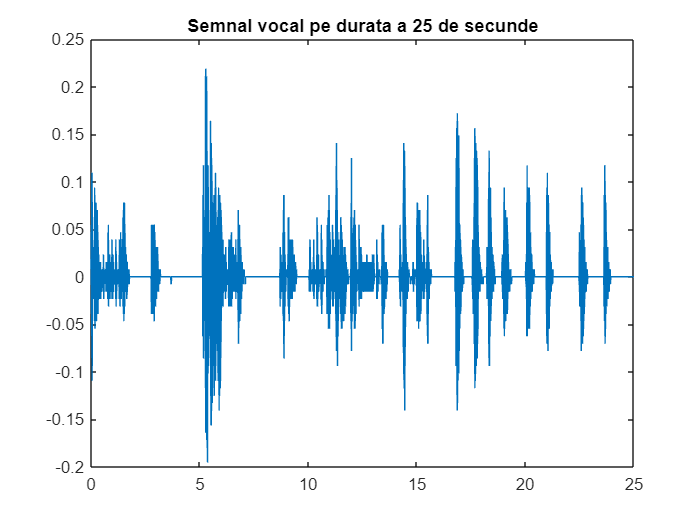

voice = getaudiodata(myVoice);
Te = sec/length(voice);
t = 0:Te:sec-Te;
plot(t,voice);
title('Semnal vocal pe durata a 25 de secunde');

#### Spectrul semnalelor audio

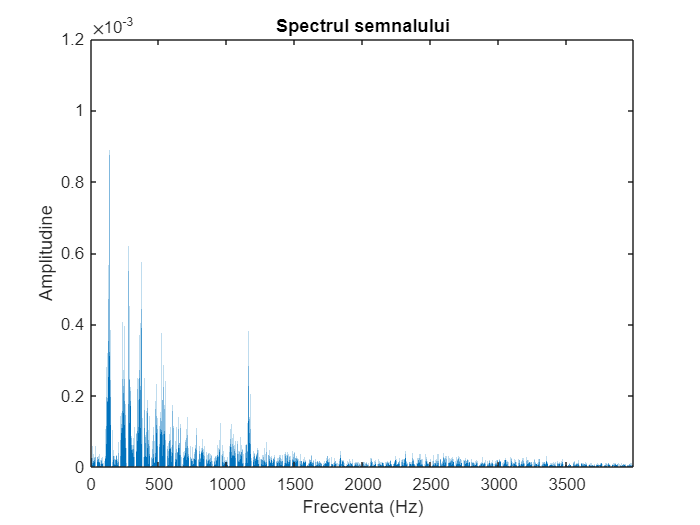

Fs=1/Te;
genSpectru(voice, Fs)

- Spectrul cu fft pe 1 secunda.

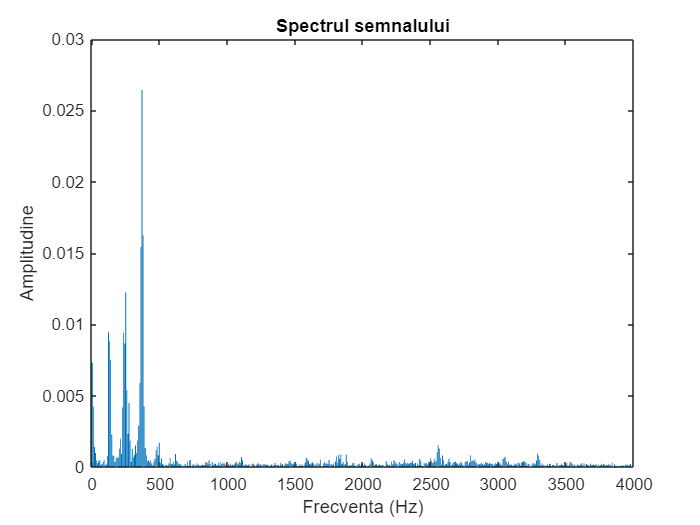

n=1e3;
v1=voice(1:n);
genSpectru(v1, 1/Te)

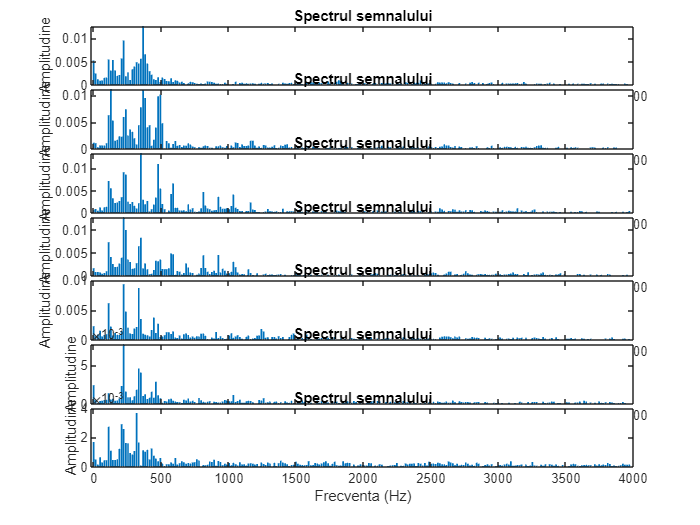

warning('off')

n=5e2;
for i=1:7
    v=voice(i*n:(i+1)*n);
    subplot(7,1,i);
    ax = gca;
    ax.Position(4) = 1.3*ax.Position(4);
    genSpectru(v, 1/Te);
end

## Cerinta:

### Proiectati un filtru numeric de tip trece banda care treaca frecventele din banda de 80 la 300Hz

• utilizati functia **fir1** pentru a genera modelul filtrului

• utilizati functia **freqz** pentru a genera raspunsul in frecventa (diagrama Bode)

• utilizati functia **filtfilt** pentru a filtra semnalul

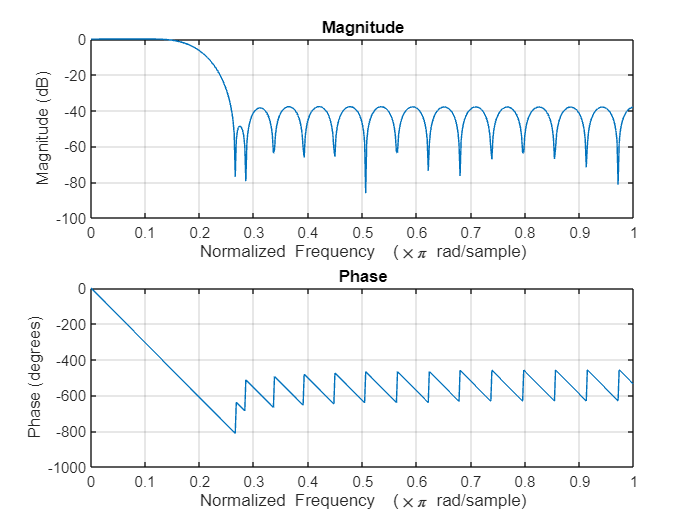

OF=34;
ft_n=500*pi/Fs;
b = fir1(OF,ft_n,'low',chebwin(35,30));
freqz(b,1,512);

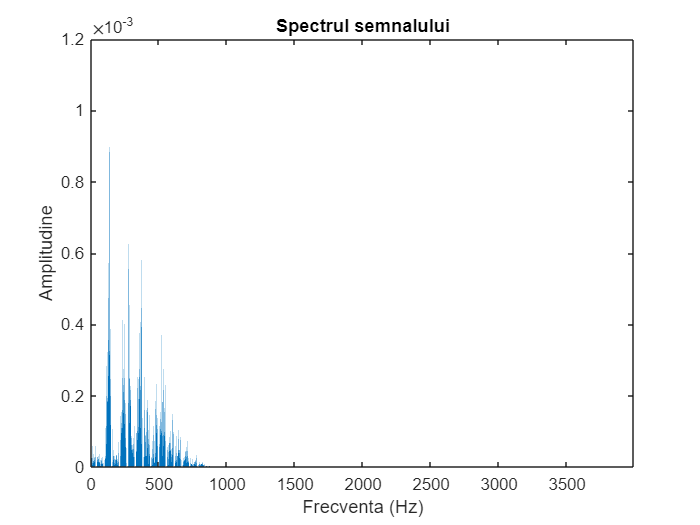

filtered_voice = filtfilt(b,1,voice);
genSpectru(filtered_voice,Fs)

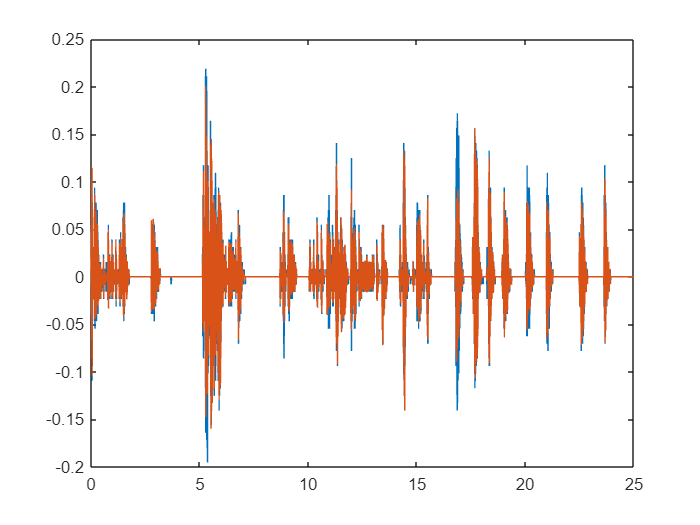

plot(t,voice,t,filtered_voice)